data = readtable('C:\Users\thoma\Downloads\per20minut.xlsx'); 
data = flipud(data); 
data.Date = datetime(data.Date,'ConvertFrom','excel'); 
data.Ret = [nan; 100*diff(log(data.Open))]

data = 6489×6 table
           Date             Open      High      Low      Close        Ret   
    ___________________    ______    ______    ______    ______    _________

    27/02/2018 09.00.00    3468.3    3476.2    3464.6    3465.2          NaN
    27/02/2018 09.20.00    3464.6    3472.4    3463.6    3467.3     -0.10703
    27/02/2018 09.40.00    3466.7    3467.2      3461    3461.5     0.060018
    27/02/2018 10.00.00    3461.2    3462.5    3459.3    3461.6     -0.15878
    27/02/2018 10.20.00    3461.5    3464.3    3458.2    3458.2     0.010978
    27/02/2018 10.40.00    3458.5    3464.5    3458.5    3464.1     -0.08815
    27/02/2018 11.00.00    3464.4    3465.9    3460.9    3461.8      0.17247
    27/02/2018 11.20.00    3462.3    3464.4    3461.4    3464.1    -0.061789
    2

startingVals = [nanmean(data.Ret),1,0.03, 0.09, 0.90];
nanmean(data.Ret)

ans = -0.0013

logreturn=data.Ret

logreturn =        NaN
   -0.1070
    0.0600
   -0.1588
    0.0110
   -0.0882
    0.1725
   -0.0618
    0.0528
   -0.1496


LB = [10*nanmean(data.Ret) -1 0 0 0]; 
UB = [-10*nanmean(data.Ret) 1 1 2 1]; 
A = [0 0 1 0.5 1]; 
b = 1;
T = size(data.Ret,1); 
w = .06*.94.^(0:T-2); 
backCast= w*data.Ret(2:end).^2; 
options = optimset('fmincon'); 
options.Display = 'iter'; 
options.Algorithm = 'sqp'; 

estimates = fmincon(@gjr_garch_likelihood, startingVals, A, b, [], [], LB, UB, [], options, data.Ret(2:1500), backCast);

Your initial point x0 is not between bounds lb and ub; FMINCON
shifted x0 to satisfy the bounds.
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           6    6.526003e+02     0.000e+00     1.000e+00     0.000e+00     7.350e+03  
Objective function returned complex; trying a new point...
    1          14   -2.209458e+03     0.000e+00     4.900e-01     5.012e-01     6.995e+04  
    2          29   -2.213101e+03     0.000e+00     4.035e-02     4.489e-02     1.866e+04  
Objective function returned complex; trying a new point...
    3          38   -2.363762e+03     0.000e+00     3.430e-01     3.581e-01     2.605e+03  
Objective function returned complex; trying a new point...
    4          49   -2.365558e+03     0.000e+00     1.681e-01     6.557e-02     1.236e+04  
    5          57   -2.367169e+03     0.000e+00     4.900e-01     2.268e-01     1.08

startingvalues2=estimates

startingvalues2 =     0.0046    0.0009    0.1434    0.0620    0.7773


[estimates2,fval,output,exitflag,lambda,grad,hessian] = fmincon(@gjr_garch_likelihood, startingVals, A, b, [], [], LB, UB, [], options, data.Ret(2:end), backCast);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           6   -9.315357e+03     0.000e+00     1.000e+00     0.000e+00     1.858e+05  
    1          28   -9.344677e+03     0.000e+00     3.323e-03     1.201e-03     6.379e+04  
    2          39   -9.371699e+03     0.000e+00     1.681e-01     1.334e-01     1.931e+04  
    3          52   -9.378929e+03     0.000e+00     8.235e-02     1.694e-01     4.626e+04  
    4          61   -9.384063e+03     0.000e+00     3.430e-01     2.820e-01     1.822e+04  
    5          73   -9.387757e+03     0.000e+00     1.176e-01     8.322e-02     1.800e+04  
    6          81   -9.389889e+03     0.000e+00     4.900e-01     1.542e-01     1.797e+03  
    7          91   -9.392910e+03     0.000e+00     2.401e-01     5.917e-02     4.333e+04  
    8         103   -9.394294e+03     0.000e+00     1.176e-01     7.332e-02     2.

hessian

hessian = 	1.0e+07 *

    0.0405    0.0430    0.0003    0.0006    0.0007
    0.0430    6.2752    0.0588    0.0275    0.1089
    0.0003    0.0588    0.0011    0.0005    0.0013
    0.0006    0.0275    0.0005    0.0003    0.0006
    0.0007    0.1089    0.0013    0.0006    0.0021


fval

fval = -9.4084e+03

output

output = 2

exitflag

exitflag = struct with fields:
         iterations: 19
          funcCount: 178
          algorithm: 'sqp'
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the default value of the step size tolerance and constraints are ↵satisfied to within the selected value of the constraint tolerance.↵↵Stopping criteria details:↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.↵↵Optimization Metric                                           Options↵max(abs(delta_x./x)) =   8.96e-07                       StepTolerance =   1e-06 (default)↵relative max(constraint violation) =   0.00e+00   ConstraintTolerance =   1e-06 (selected)'
    constrviolation: 0
           stepsize: 1.2133e-06
       lssteplength: 0.7000
      firstordero

lambda

lambda = struct with fields:
         eqlin: [0×1 double]
      eqnonlin: [0×1 double]
       ineqlin: 0
    ineqnonlin: [0×1 double]
         lower: [5×1 double]
         upper: [5×1 double]


grad

grad =    -0.0127
    0.1691
   -0.0059
   -0.0040
   -0.0021


eig(hessian)

ans = 	1.0e+07 *

    0.0001
    0.0001
    0.0008
    0.0402
    6.2781


lambda

lambda = struct with fields:
         eqlin: [0×1 double]
      eqnonlin: [0×1 double]
       ineqlin: 0
    ineqnonlin: [0×1 double]
         lower: [5×1 double]
         upper: [5×1 double]


estimates2

estimates2 =     0.0007    0.0040    0.2043    0.1123    0.5728


[ll,lls,h]=gjr_garch_likelihood(estimates, data.Ret(2:end), backCast)

ll = -9.3154e+03

lls =    -1.6660
   -1.9664
   -1.1594
   -2.0309
   -1.8145
   -1.1029
   -1.9327
   -2.0481
   -1.2090
   -0.7276


h =     0.0162
    0.0161
    0.0139
    0.0172
    0.0143
    0.0138
    0.0157
    0.0140
    0.0121
    0.0152


% resid(data.Ret(2:end),h)

options = optimset('fminunc');
options = optimset(options,'Display','iter');
startingVals = [nanmean(data.Ret),nanvar(data.Ret) * .01,.03, .09, .90];

[ll,lls,h]=gjr_garch_likelihood(estimates, data.Ret(2:end), backCast)

ll = -9.3154e+03

lls =    -1.6660
   -1.9664
   -1.1594
   -2.0309
   -1.8145
   -1.1029
   -1.9327
   -2.0481
   -1.2090
   -0.7276


h =     0.0162
    0.0161
    0.0139
    0.0172
    0.0143
    0.0138
    0.0157
    0.0140
    0.0121
    0.0152


%  est=fminunc(@gjr_garch_likelihood, options, startingVals);
% [ll,lls,h]=gjr_garch_likelihood(estimates, p0, data.Ret(2:end), backCast)
logreturn(2:end)

ans =    -0.1070
    0.0600
   -0.1588
    0.0110
   -0.0882
    0.1725
   -0.0618
    0.0528
   -0.1496
   -0.1982


% mean(logreturn(2:end)./sqrt(h))
mean((logreturn(2:end)./sqrt(h)).^2)

ans = 1.2154

mean((logreturn(2:end)./sqrt(h)).^3)

ans = 0.0766

mean((logreturn(2:end)./sqrt(h)).^4)

ans = 12.7598


mean(lls)

ans = -1.4358

eig(lls*lls')

ans = 	1.0e+04 *

   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


mean(ll)

ans = -9.3154e+03

% eig(lls)
h

h =     0.0162
    0.0161
    0.0139
    0.0172
    0.0143
    0.0138
    0.0157
    0.0140
    0.0121
    0.0152


z=(logreturn-estimates(:,1))/h
mean=mean(z)
var=var(z)
skew=skewness(z)
kurtosis=kurtosis(z)
step = 1e-5*estimates; 
bidrag = zeros(T-1,5); 
for i=1:5 
    h = step(i); 
    delta = zeros(1,5); 
    delta(i) = h;
[~, logliksplus] = gjr_garch_likelihood(estimates + delta, data.Ret(2:end), backCast); 
[~, logliksminus] = gjr_garch_likelihood(estimates - delta, data.Ret(2:end), backCast);
bidrag(:,i) = (logliksplus - logliksminus)/(2*h);
end
I = bidrag'*bidrag/T; 
mean(bidrag)

ans =     0.1278  -28.6448   -0.1621   -0.0989   -0.2301


J = hessian_2sided(@gjr_garch_likelihood, estimates, data.Ret(2:end), backCast);
J = J/T; 
Jinv = J\eye(length(J)); 
vcv = Jinv*I*Jinv/T

vcv =     0.0000   -0.0000   -0.0000    0.0000    0.0000
   -0.0000    0.0000    0.0000   -0.0000   -0.0000
   -0.0000    0.0000    0.0034   -0.0011   -0.0032
    0.0000   -0.0000   -0.0011    0.0008    0.0008
    0.0000   -0.0000   -0.0032    0.0008    0.0034


[h,pValue,stat,cValue]=lbqtest(z,'lags',5)
pvaerdiforar=pValue
[h,pValue,stat,cValue]=lbqtest(z,'lags',5)
pvaerdiforarch=pValue
[h,p,jbstat,critval]=jbtest(z)
pvaerdifornormalitet=p
plot(z)
xlabel('datoer')
ylabel('fejlled')
title('plot af fejlled')
print(z)
output = [estimates', sqrt(diag(vcv)), estimates'./sqrt(diag(vcv)), ll, pvaerdiforarch, pvaerdiforar,pvaerdifornormalitet,mean, var, skewness, kurtosis]; 
disp(' Parameter Estimate Std. Err. T-stat loglikelihood pvaerdiforarch pvaerdiforar pvaerdifornormalitet mean var skewness kurtosis') 

 Parameter Estimate Std. Err. T-stat


param = {'mu','omega','alpha','gamma','beta','loglikelihood', 'pvaerdiforarch', 'pvaerdiforar', 'mean', 'var', 'skewness', 'kurtosis'; 
for i = 1:5
    fprintf('%10s %10.3f %13.3f %11.3f \n',param{i},output(i,1),output(i,2),output(i,3)); 
end

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

        mu      0.005         0.002       2.638 


     omega      0.001         0.000       3.686 


     alpha      0.143         0.058       2.475 


     gamma      0.062         0.029       2.140 


      beta      0.777         0.058      13.356 


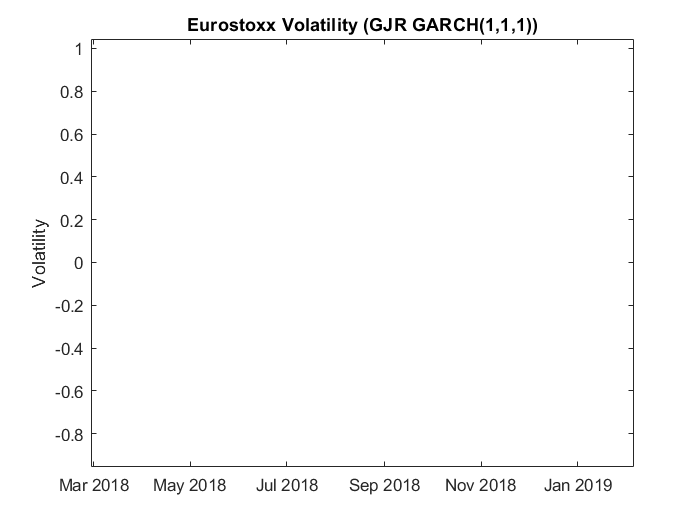

% end
mu=estimates(:,1)/100;
omega=estimates(:,2)/10000;
alpha=estimates(:,3);
gamma=estimates(:,4);
beta=estimates(:,5);




s=rng;
tilfaeldige=trnd(8000,121,1000);
sigma2=zeros(121,1000);
sigma2(1,:)=h(end)/10000;
y=zeros(121,1000);
S=zeros(121,1000);
% sigma2(1)=0.3879/10000;
r=zeros(121,1000);
theta=zeros(121,1000);
m=zeros(121,1000);
m(1,:)=1

m =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

r(1,:)=0;
S(1,:)=1

S =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

y=zeros(121,1000);

rent=0.003/251

rent = 1.1952e-05

for j=1:1000
for i=2:121
    sigma2(i,j)= omega + alpha * y(i-1,j)^2 + gamma * y(i-1,j)^2 * (y(i-1,j)<0) + beta * sigma2(i-1,j);
    y(i,j)=sqrt(sigma2(i,j))*tilfaeldige(i,j)+mu;
    r(i,j)=y(i,j)+r(i-1,j);
    S(i,j)=exp(r(i,j));
    theta(i,j)=rent/sigma2(i,j)-1/2;
    m(i,j)=exp(y(i,j)*theta(i,j))/exp((1+theta(i,j))^2.*sigma2(i,j)/2);
    
end
end
option=exp(-0.00001*30)*mean(max(S(30,:)-K,0))

option = 0.0028

option2=mean(max(S(30,:)-K,0))*mean(prod(m(30)))

option2 = 0.0028


option2=mean(max(S(30,:)-K,0)*(prod(m(30))))*data.PX_LAST(end)

option2 = 8.3656




option=exp(-0.00001*60)*mean(max(S(60,:)-K,0))

option = 0.0050

option2=mean(max(S(60,:)-K,0)*prod(60))*3000

option2 = 894.0645


option2=mean(max(S(60,:)-K,0))*mean(prod(m(60)))

option2 = 0.0049

option2=mean(max(S(60,:)-K,0))*mean(prod(m(60)))*3000

option2 = 14.6909

option2=mean(max(S(60,:)-K,0)*(prod(m(60))))*data.PX_LAST(end)



option=exp(-0.00001*90)*mean(max(S(90,:)-K,0))

option = 0.0071

option2=mean(max(S(90,:)-K,0)*prod(90))*3000

option2 = 1.9076e+03

option2=mean(max(S(90,:)-K,0))*mean(prod(m(90)))

option2 = 0.0070

option2=mean(max(S(90,:)-K,0)*(prod(m(90))))*data.PX_LAST(end)

option2 = 20.9268



option=exp(-0.00001*120)*mean(max(S(120,:)-K,0))

option = 0.0086

option2=mean(max(S(120,:)-K,0)*(prod(m(120))))*data.PX_LAST(end)

option2 = 3.0995e+03

option2 = 0.0086

option2 = 25.7156

option2 = 0.0124

function [ll,lls,h] = gjr_garch_likelihood(parameters, data, backCast)
mu = parameters(1);
omega = parameters(2);
alpha = parameters(3);
gamma = parameters(4);
beta = parameters(5);
lambda=parameters(6);
T = size(data,1);
h = zeros(T,1);
h(1) = backCast;
v=length(data)-length(parameters);
for i = 2:T 
    eps(i) = data(i) - mu+lambda*h(i)-h(i)/2; 
    h(i) = omega + alpha * eps(i-1)^2 + gamma * eps(i-1)^2 * (eps(i-1)<0) + beta * h(i-1); 
end
if v<50
    v = 2 + exp(v);
else
    v = 50 + log(v);
end
% lls = 0.5*(log(2*pi) + log(h) + eps.^2./h);
lls=0.5*(log(h)+(v+1)*log(1+eps.^2./(h.*(v-1))));

ll = sum(lls);
end
function H = hessian_2sided(fun, theta, varargin)
if size(theta,2)>size(theta,1) 
    theta = theta';
end

f = feval(fun,theta,varargin{:});
h = 1e-5 * abs(theta);
thetah = theta + h;
h = thetah - theta;
K = size(theta,1);
h = diag(h);
fp = zeros(K,1);
fm = zeros(K,1);
for i = 1:K
    fp(i) = feval(fun, theta+h(:,i),varargin{:});
    fm(i) = feval(fun, theta-h(:,i),varargin{:});
end
fpp = zeros(K);
fmm = zeros(K);
for i = 1:K
    for j = i:K
        fpp(i,j) = fun(theta + h(:,i) + h(:,j), varargin{:});
        fpp(j,i) = fpp(i,j);
        fmm(i,j) = fun(theta - h(:,i) - h(:,j), varargin{:});
        fmm(j,i) = fmm(i,j);
    end
end 
hh = diag(h);
hh = hh*hh';
H = zeros(K);
for i=1:K
    for j=i:K
        H(i,j) = (fpp(i,j) - fp(i) - fp(j) + f+ f - fm(i) - fm(j) + fmm(i,j))/hh(i,j)/2;
        H(j,i) = H(i,j);
    end
end
end